# Spectral Analysis - My First FFT

Spectral analysis is the quantitative analysis of the frequency content of a signal, such as a sound waveform. We’ll work through a simple example using the sum of sinusoids. 

## Set up variables

First, let’s set up some variables. This includes the sampling frequency `Fs`, which defines the number of samples per second for our signal.

Fs = 8192  % Sampling frequency, in samples/s (i.e Hz)

Fs = 8192

L = Fs/2   % Length of audio segment we will create, in samples

L = 4096

f1 = 400   % Frequency of first sinusoid, in Hz

f1 = 400

f2 = 600   % Frequency of second sinusoid, 1.5*f1

f2 = 600

We need to create a vector of time points, with units of seconds. The total length of the vector will be `L` samples spanning 0.5 seconds

t = (0:L-1)/Fs

t =          0    0.0001    0.0002    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0048    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060


Next, we generate two sinusoids and add them together

y1 = 0.5*sin(2*pi*f1*t)

y1 =          0    0.1510    0.2879    0.3979    0.4708    0.4997    0.4819    0.4191    0.3172    0.1857    0.0368   -0.1155   -0.2571   -0.3746   -0.4571   -0.4970   -0.4904   -0.4380   -0.3448   -0.2193   -0.0734    0.0794    0.2248    0.3492    0.4410    0.4916    0.4962    0.4546    0.3705    0.2518    0.1096   -0.0429   -0.1913   -0.3219   -0.4224   -0.4835   -0.4994   -0.4687   -0.3942   -0.2829   -0.1451    0.0061    0.1568    0.2929    0.4016    0.4728    0.4998    0.4802    0.4157    0.3124


y2 = 0.5*sin(2*pi*f2*t)

y2 =          0    0.2221    0.3979    0.4910    0.4819    0.3725    0.1857   -0.0398   -0.2571   -0.4208   -0.4970   -0.4697   -0.3448   -0.1481    0.0794    0.2904    0.4410    0.4998    0.4546    0.3148    0.1096   -0.1185   -0.3219   -0.4583   -0.4994   -0.4365   -0.2829   -0.0703    0.1568    0.3514    0.4728    0.4959    0.4157    0.2491    0.0307   -0.1942   -0.3786   -0.4843   -0.4892   -0.3923   -0.2138    0.0092    0.2303    0.4034    0.4926    0.4794    0.3663    0.1771   -0.0490   -0.2649


y = y1 + y2

y =          0    0.3731    0.6858    0.8889    0.9527    0.8722    0.6675    0.3793    0.0601   -0.2351   -0.4602   -0.5853   -0.6018   -0.5226   -0.3777   -0.2065   -0.0494    0.0617    0.1098    0.0955    0.0362   -0.0391   -0.0971   -0.1092   -0.0584    0.0550    0.2134    0.3843    0.5273    0.6031    0.5824    0.4530    0.2244   -0.0728   -0.3918   -0.6777   -0.8780   -0.9529   -0.8833   -0.6751   -0.3589    0.0153    0.3871    0.6963    0.8942    0.9522    0.8662    0.6573    0.3667    0.0475


To hear what these sound like, try using the sound function in the Command Window for the two sinusoids separately and then the sum, e.g `sound(y1,Fs)` or `sound(y,Fs)`. The summed result sounds pleasant, yes? You may also be able to hear a short clipping sound at the start and end of the sound. That’s because the onset and offset of our sound is very sharp; we would need to slowly ramp up the amplitude to avoid the clipping sound. We’ll come back to this, but for now, let’s plot the waveforms to see what they look like.

## Plotting the waveforms

This code snippet will plot the two individual sinusoids. We'll use the `tiledlayout` function to place two sets of axes on the same figure. 

tiledlayout(2,1) 
nexttile
plot(t,y1), hold on
plot(t,y2), hold off
xlim([0 0.02]), ylim([-1.5 1.5])
box off
xlabel("Time (s)"), ylabel("Amplitude")
legend(f1 + " Hz sinusoid",f2 + " Hz sinusoid")
title("Individual sinusoids")

Now we plot the sum. To make this new set of axes, we call `nexttile` again.  

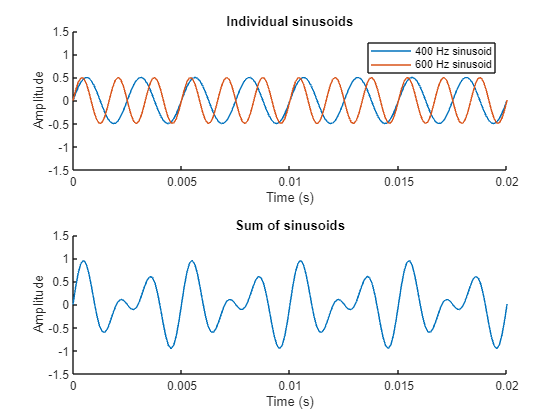

nexttile
plot(t,y)
xlim([0 0.02]), ylim([-1.5 1.5])
box off
xlabel("Time (s)")
ylabel("Amplitude")
title("Sum of sinusoids")

## Calculating the discrete Fourier transform

To look at this signal in the frequency domain, we will use the `fft` function to take the discrete Fourier transform of our vector `y` (discrete because we have a vector of discrete points instead of a continuous function). Fun historical fact: the letters FFT stand for “Fast Fourier Transform”, a name that has stuck since 1965 when J.W. Cooley and John Tukey published a paper on the basic algorithm. The improvement in computation time provided by this algorithm revolutionized the field of digital signal processing, although it was later discovered that Carl Friedrich Gauss had described the same algorithm in 1805!

An optional input to `fft` is the number of frequency points to evaluate. We will choose the length of the vector `L`, which is the default value had you simply called `fft(y)`

NFFT = L           % Number of FFT points. 

NFFT = 4096

Y = fft(y,NFFT)    % Discrete fourier transform

Y = 1.0e+03 *

  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i


`Y` is a vector of complex values the same length as `y`, but it contains the signal amplitude as a function of frequency, not time. To make sense of these values, we need to define these frequencies in a vector. 

f = Fs/2*(0:NFFT/2)/(NFFT/2);

f =      0     2     4     6     8    10    12    14    16    18    20    22    24    26    28    30    32    34    36    38    40    42    44    46    48    50    52    54    56    58    60    62    64    66    68    70    72    74    76    78    80    82    84    86    88    90    92    94    96    98


Next, we extract the portion of `Y` that corresponds to these frequencies (only half due to the nature of the FFT). We also use the absolute value function `abs` to get the magnitude. To extract the phase, you would use the function `angle`.

Ymag = abs(Y(1:NFFT/2+1));

Ymag = 1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Finally, we can plot the result.

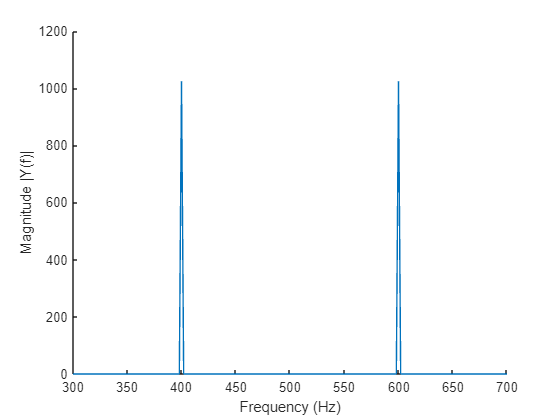

plot(f,Ymag)
xlim([300 700])
box off
xlabel("Frequency (Hz)")
ylabel("Magnitude |Y(f)|")

You can see we have two peaks at 400 and 600 Hz, suggesting that these are the only frequencies that our signal contains. You might nod your head at that statement, but it’s actually not true. Remember when we mentioned the clipping noises you can hear when you play the sound? This has an affect on the frequency spectrum as well, but we can’t see it in the figure above due to our careful choice of parameters.

To make this effect visible, try increasing the number of FFT points, e.g. `NFFT = 5*L`. This increases the frequency resolution of the FFT, meaning finer spacing along the frequency axis.

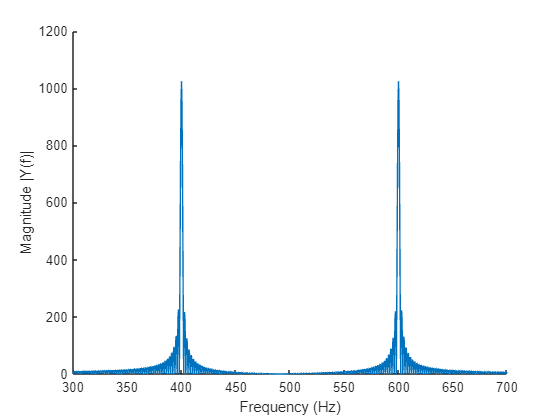

NFFT = 5*L;
Y = fft(y,NFFT);
f = Fs/2*(0:NFFT/2)/(NFFT/2);
Ymag = abs(Y(1:NFFT/2+1));

plot(f,Ymag)
xlim([300 700])
box off
xlabel("Frequency (Hz)")
ylabel("Magnitude |Y(f)|")

As you can see, our peaks appear to be significantly wider. The interesting thing is that these sidelobes were always present, we merely hid them previously by choosing the frequencies where the magnitude was zero and connecting those points with a straight line. This gives the false appearance of a smooth frequency spectrum. 

To briefly explain what’s going on here, we’ve increased the frequency resolution to reveal the effect of a process called **windowing**. You can think of our signal (0.5 second-long sinusoid) as a “windowed” version of the actual signal $y = sin(t)$, which is defined from $-\infty$ to $+\infty$. Windowing the signal in the time domain produces what engineers call **leakage** in the frequency domain, meaning the energy has “leaked” from the main frequency into nearby frequencies. This leakage is what we see as wider peaks.